# Tutorial: OCT file reading and visualization

This tutorial shows how to:

- Load OCT files

- Visualize loaded data (fundus image, OCT slices, segmentation...)

- Generate a summary report including all relevant images.

If you need help please reach out at **dromero@mondragon.edu**

clc; clearvars; close all;
addpath(genpath('../src'));

### Read OCT file

RETIMAT supports .vol, .e2e, .img, .bin and .fda formats.

Although the API is similar, each format has a different way of structuring the data.

In this tutorial we will work with a .vol file but all the APIs are described below

#### Spectralis (.vol)

.vol files contain a single OCT volume along with fundus image and segmentation data.

file = '../src/data/raster.vol';
[header, seg, bscan, fundus] = read_vol(file);

#### Spectralis (.e2e)

E2E files can contain multiple OCT volumes. They usually contain two (one per eye).

Therefore the returned objects are cell lists each refereing to a single OCT acquisition.

% [header, seg, bscan, fundus] = read_e2e(file);

#### Cirrus (.img/.bin)

Cirrus img files only contain raw OCT slices. Therefore segmentation is not available.

The *read_img* function reads the B-scans in the file and tries to infer the header metadata from image size and file name.

The fundus image acquired along with the img is stored in a separated .bin file

% [header,bscan] = read_img(file);

% fundus = read_bin(file);

#### Topcon (.fda)

fda files contain metadata, fundus, OCT and segmentation data. 

To read a file:

% [header, seg, bscan, fundus] = read_fda(file);

### Plot header

The header is a structure with metadata information (fixation, scaling...).

We can check the info in header as:

disp(header)

          fixation: 'macula'
     bscan_pattern: 'raster'
           n_ascan: 512
           n_bscan: 25
           n_axial: 496
           scale_x: 0.0124
           scale_y: 0.2650
           scale_z: 0.0039
     size_x_fundus: 768
     size_y_fundus: 768
    scale_x_fundus: 0.0124
    scale_y_fundus: 0.0124
        fov_fundus: 30
        patient_id: 'E01'
               eye: 'OD'
        scan_focus: -4.6375
             X_fun: [768×768 double]
             Y_fun: [768×768 double]
             X_oct: [25×512 double]
             Y_oct: [25×512 double]



Header structure is an attempt at harmonizing data from different scanners. 

Fields should be equivalent across scanners. However, due to the difficulty of fully reading propietary file formats not all the fields will be present for every format.

In some cases a larger version of the header can be read by adding the *full_reader *flag

[header, seg, bscan] = read_vol(file, 'full_header')

#### Segmented boundaries

boundaries = fields(seg);
disp(boundaries')

  Columns 1 through 9

    {'ILM'}    {'BM'}    {'RNFL_GCL'}    {'GCL_IPL'}    {'IPL_INL'}    {'INL_OPL'}    {'OPL_ONL'}    {'ELM'}    {'MZ_EZ'}

  Columns 10 through 11

    {'OSP_IZ'}    {'IZ_RPE'}



#### Visualize fundus image (slo)

Often a fundus image is acquired alongside the OCT volume. Depending on the scanner this image is different:

- Spectralis: a graysacle image stored inside .vol/.e2e files.

- Cirrus: a grayscale image stored in a .bin file

- Topcon: a RGB color image store inside .fda files.

In any case it is useful to visualize the fundus image to inspect the retina and validate fixation or detect lessions.

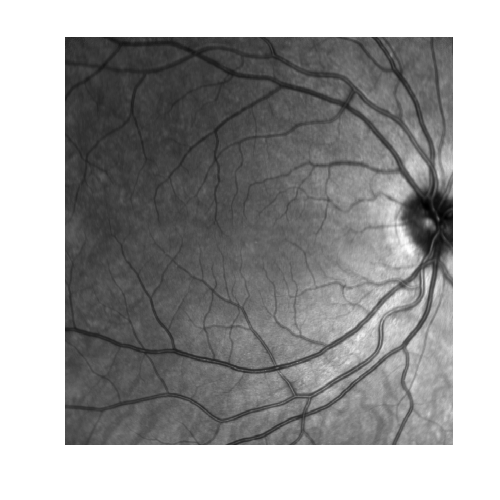

f = figure('Position',[0 0 400 400]);
imagesc(fundus); colormap(gray); axis("off");

#### Visualize OCT slices

Quality assurance should be a step in any image analysis pipeline. 

In the case of OCT poor quality images, artifacts or segmentation errors are not uncommon.

Therefore, it is crucial to inspect the data to avoid those problems.

We can plot several B-scans along with the corresponding documentation simply as:

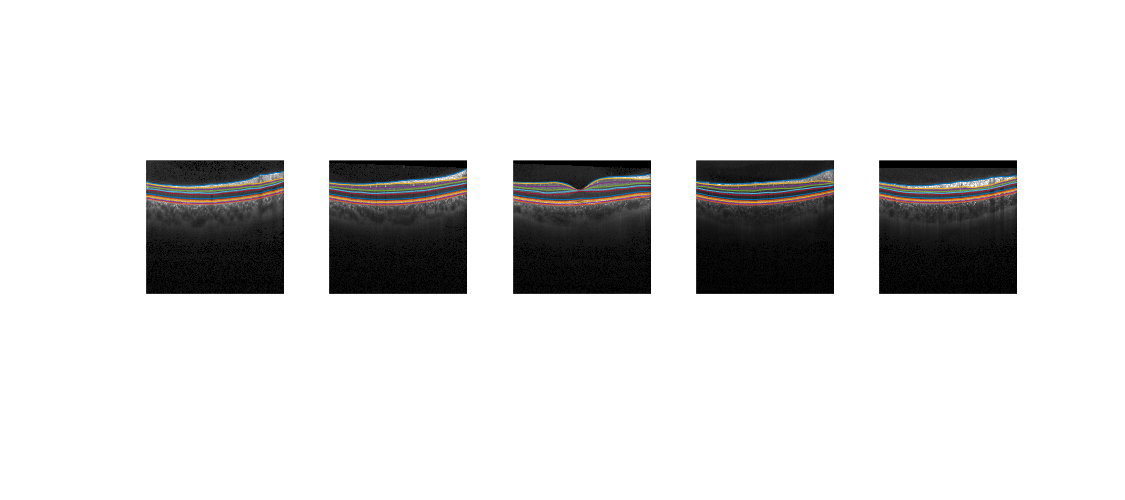

f = figure('Position',[0 0 900 400]);
idx_bscan = round(linspace(1, 25, 5));
for i=1:length(idx_bscan)
    subplot(1,5,i); hold on;
    imshow(bscan(:,:,idx_bscan(i)));
    for j=1:length(boundaries)
        plot(seg.(boundaries{j})(idx_bscan(i), :))
    end
end

#### Generating a report

Doing all the previous steps separately is not convenient.

To simplify data inspection we can automatically create a summary report using generate_report() function

The function allows us to pass fundus,bscan and segmentation data and builds a tiled plot that can be stored in memory.

A full report includes:

- Fundus image

- Reflectance map: a 2D map obtained by averaging A-scan intensities in depth. Useful to detect noisy B-scans and shades.

- Thickness maps: 2D maps generated by computing layer thicknesses from segmentation data. Useful to detect segmentation errors or lessions.

- B-scans: several slices with overlapping segmentation.

As an example, let's generate a full report for the loaded image.

As arguments we just need to image data and the layers for which we want to plot thickness maps

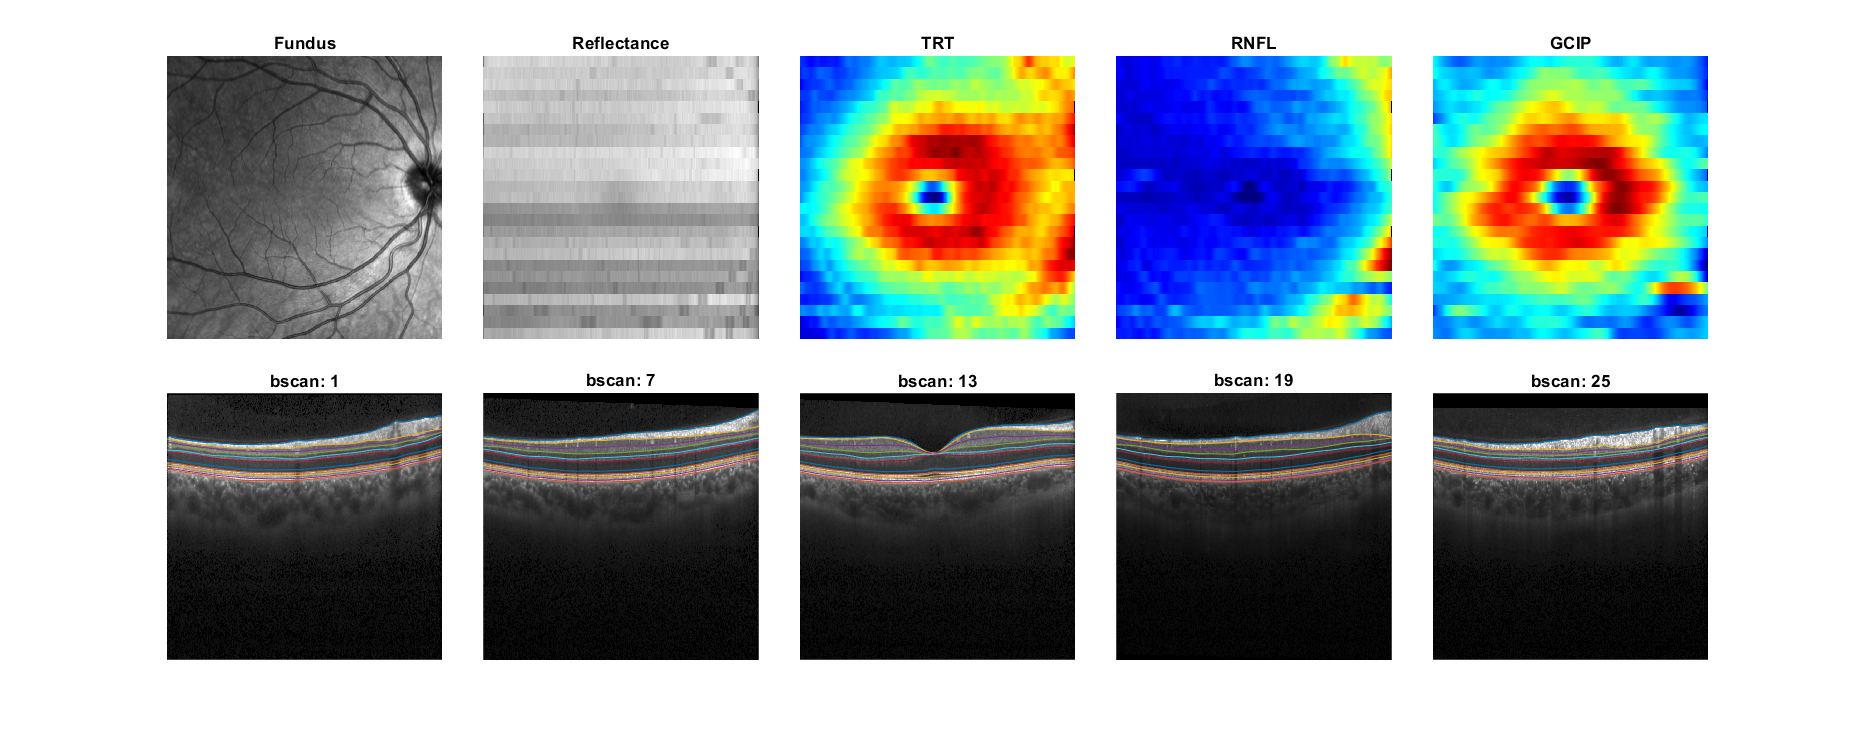

layers = {'TRT','RNFL','GCIP'};
generate_report(bscan, seg, fundus, layers);